Limpar 

close all
clear
clc

# Analise CC para emisro comum com polarização por divisor de tensão

Figura 1- Circuito base

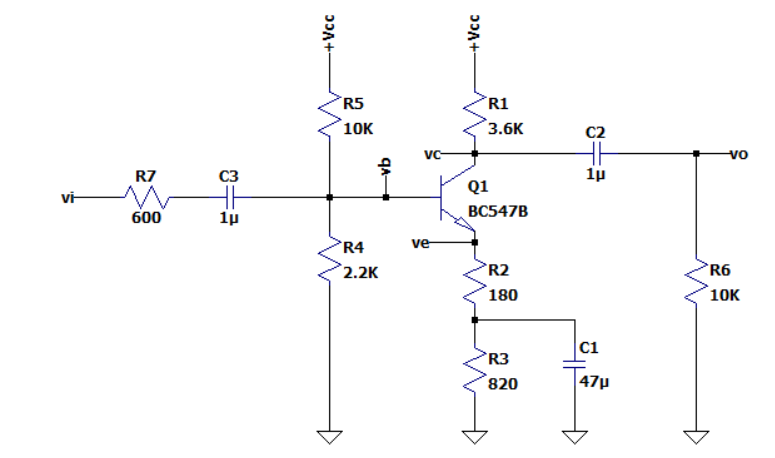

## ** Calc Analise CC (DC)**

Figura 2- Circuito para analise CC

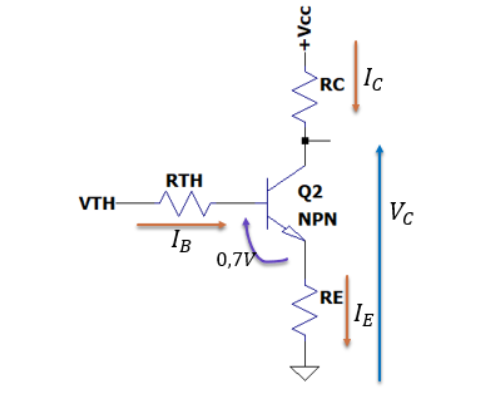

### Valores dos componentes:

R5 = 10e+3;%%Rth
R4 =2.2e+3;%%Rth
RE = 1e+3;%% R2+R3
Vcc = 10;%%Variavel de entrada
B = 290; % Beta para o calc
Vbe = 0.7; 
Vce = 5; %data sheet


### Equivalentes de TH

Vth = (R4/(R5+R4))*Vcc

Vth = 1.8033

Rth = ((1/R5)+(1/R4))^-1

Rth = 1.8033e+03

### Correntes

Ib = (Vth-Vbe)/(Rth+RE*(B+1))

Ib = 3.7680e-06

Ic = (B+1)*Ib

Ic = 0.0011

Ie = Ic

Ie = 0.0011

### Tensões CC

Vb = Vth

Vb = 0.0068

Vre = RE*Ie;
Vc = Vce+Vre

Vc = 6.0965

Ve = RE*Ie

Ve = 1.0965

## **Calc Analise CA (AC)**

Figura 3- Circuito para analise CA

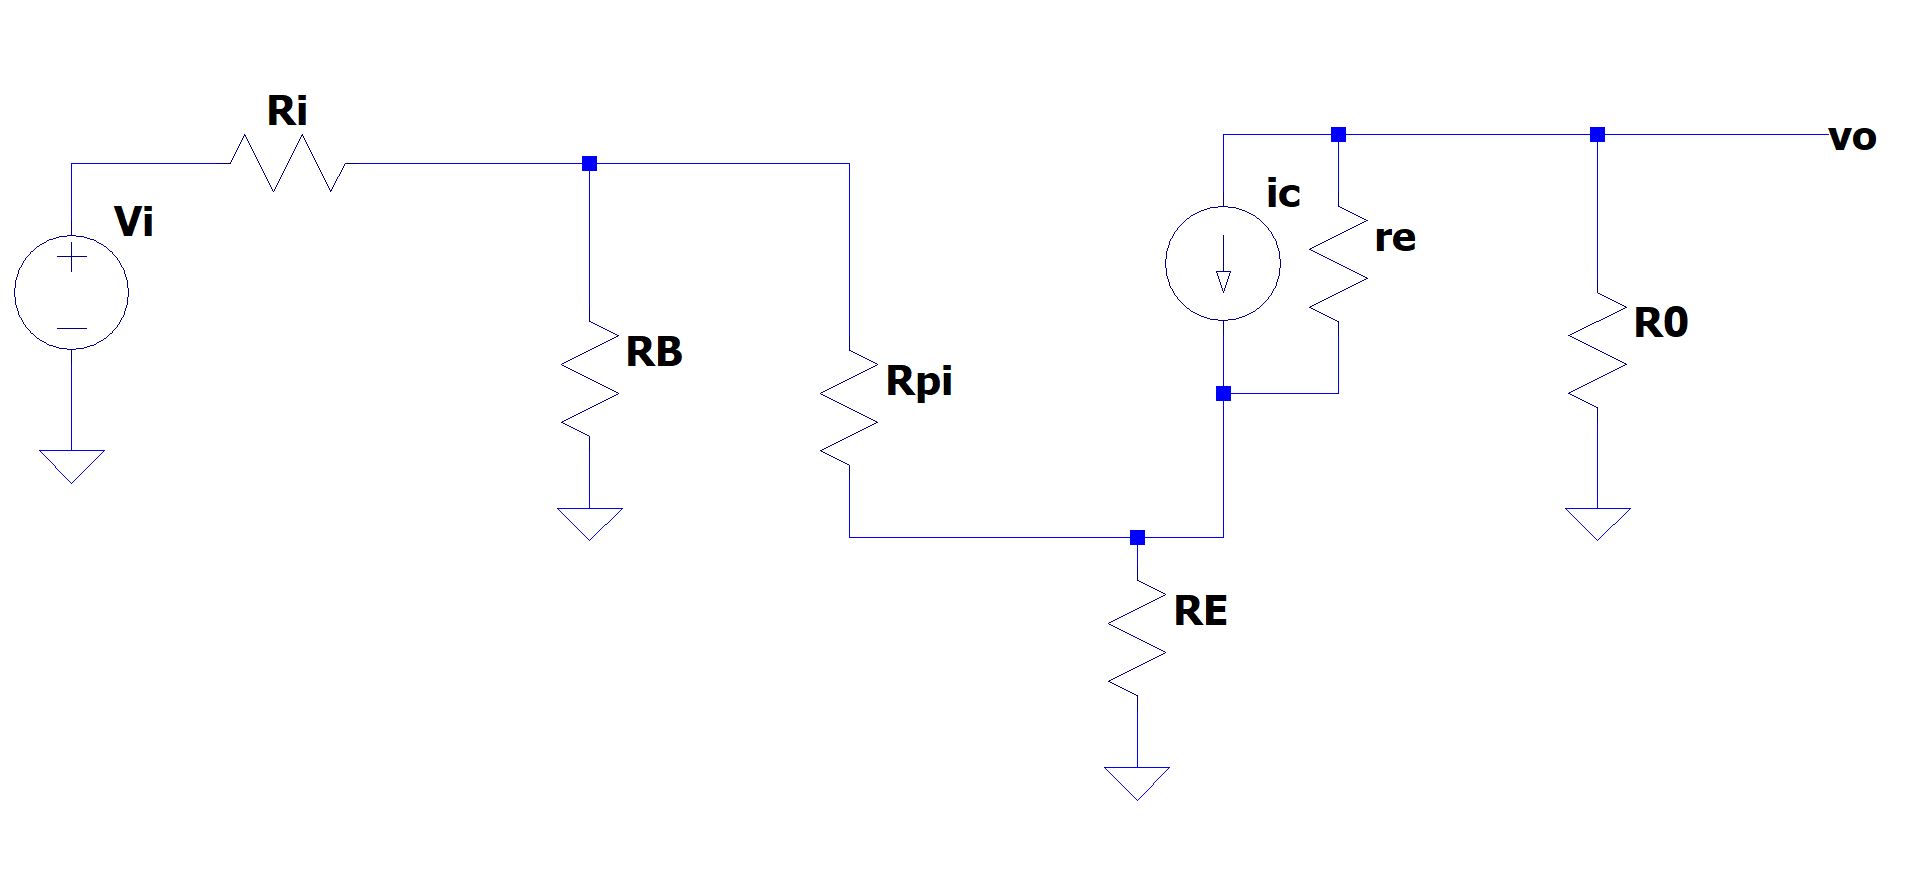

### Valores dos componentes 

*Obs.: todos os valores de componentes possuem a variavel com nome correspondente ao circuito apresentado na figura 1.

Ri = 600; %valor de entrada da figura 1
R6 = 10e+3;%valor de entrada da figura 1
R1 = 3.6e+3;%valor de entrada da figura 1
RB = Rth; %calculado
R0 = ((1/R6)+(1/R1))^-1;%calculado
RE = 180; %valor de entrada da figura 1  R2
VT = 22e-3;%% Tensão termica dado no datasheet VT = (K*T)/q


### calculo do re e rpi:

re = VT/Ie

re = 20.0641

rpi = (B+1)*re

rpi = 5.8387e+03

### Calculo das tensões e  impedâncias

v0 = -1*Ic*R0

v0 = -2.9025

vb = (B+1)*(RE+re)*Ib

vb = 0.2194

Zb = (B+1)*(RE+re)

Zb = 5.8219e+04

vi = Ib*(Ri+((Ri/RB)+1)*(B+1)*(RE+re))

vi = 0.2946

Av = v0/vi

Av = -9.8516

Zi = Ri+(((1/RB)+(1/((B+1)*(RE+re))))^-1)

Zi = 2.3491e+03

Z0 = ((1/R1)+(1/R6))^-1

Z0 = 2.6471e+03